# **Introducción a la programación en Arduino Mediante MATLAB/Simulink**

En este documento se describe al usuario los primeros pasos a seguir cuando usamos la placa de control Arduino con el modelo de Simulink. Previamente, se introducirán los paquetes de soporte MATLAB y Simulink para Arduino y se describirá como configurar Simulink para poder interactuar con Arduino (en este caso se usará un Arduino Due). Finalmente, se harán varios ejercicios respecto a las entradas y salidas analógicas y digitales.

**OBJETIVO: Aprender a usar los bloques específicos de entradas y salidas analógicas de Arduino en Simulink.**

% Si desea abrir el modelo de Simulink para hacer experimentos = true
% Si no desea abrir el modelo de Simulink = false
OpenModel = true;

# Paquetes de Soporte

Gracias a los paquetes de soporte de MATLAB/Simulink para el hardware Arduino, podemos comunicarnos e interactuar con una placa Arduino. Estos paquetes permiten adquirir datos de sensores analógicos y digitales desde la placa Arduino y controlar otros dispositivos con salidas analógicas y digitales o de modulación PWM creando así una plataforma versátil y de bajo coste.

Su instalación es muy sencilla, para ello sigue los siguientes pasos:

- En la pestaña "Home" > "Adds-Ons" > "Get Adds-Ons"

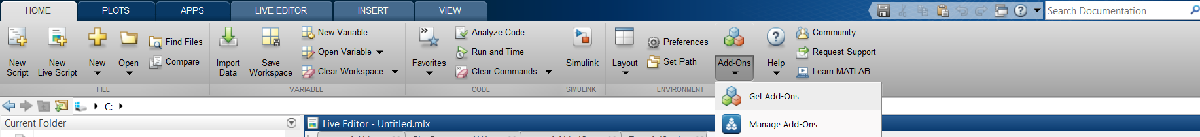

- Encontrar los paquetes mencionados y clicar en el botón instalar.

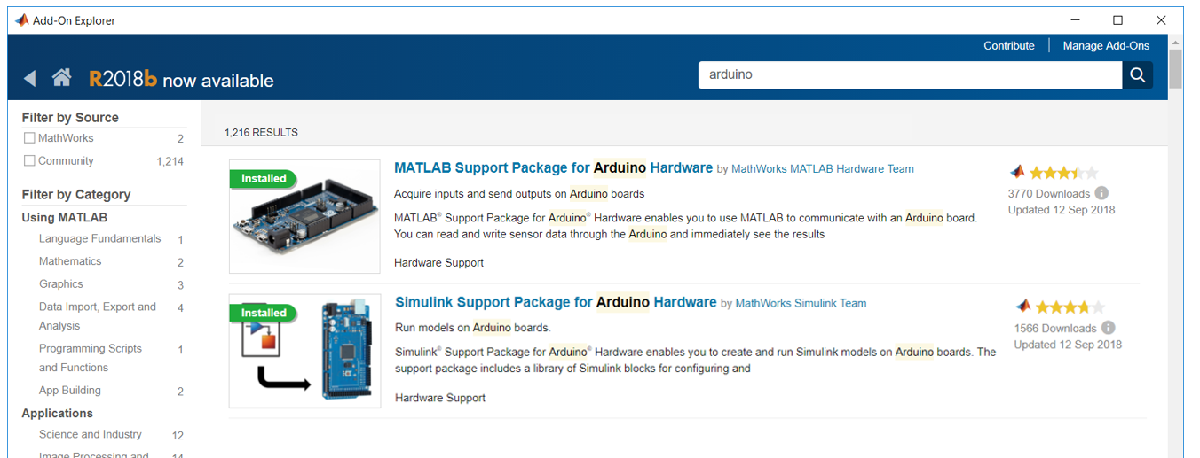

Para más información:

***Soporte de MATLAB para Arduino***

Página web: [https://es.mathworks.com/hardware-support/arduino-matlab.html](https://es.mathworks.com/hardware-support/arduino-matlab.html) 

Documentación: [http://www.mathworks.com/help/supportpkg/arduinoio/](http://www.mathworks.com/help/supportpkg/arduinoio/)

Ejemplos: [https://es.mathworks.com/help/supportpkg/arduinoio/examples.html](https://es.mathworks.com/help/supportpkg/arduinoio/examples.html) 

***Soporte de Simulink para Arduino***

Página web: [https://es.mathworks.com/hardware-support/arduino-simulink.html](https://es.mathworks.com/hardware-support/arduino-simulink.html) 

Documentación: [http://www.mathworks.com/help/supportpkg/arduino/](http://www.mathworks.com/help/supportpkg/arduino/)

Ejemplos: [https://es.mathworks.com/help/supportpkg/arduino/examples.html](https://es.mathworks.com/help/supportpkg/arduino/examples.html) 

# Configuración para MATLAB

Para conectarte a un hardware oficial de Arduino.

a = arduino()

Si está utilizando un hardware Arduino no oficial (clon), especifique el puerto y el nombre de la placa para establecer la conexión.

a = arduino('COM3','Uno')

El paquete de soporte de MATLAB para Arduino proporciona una lista de funciones que permiten acceder a entradas y salidas digitales y analógicas: 

- configurePin: establece la direccionalidad (entrada o salida) de un pin digital. 

- writeDigitalPin - escribe en una salida digital. 

- readDigitalPin - lee una entrada digital. 

- writePWMDutyCycle: escribe en una salida PWM, ciclo de trabajo en 0-1. 

- writePWMVoltage: escribe en una salida PWM, ciclo de trabajo en 0-5 (voltios efectivos). 

- readVoltage - lee una entrada analógica.

Puede encontrar una descripción detallada de cada función en MATLAB usando su ayuda o mediante la documentación proporcionada en el apartado anterior.

# Configuración para Simulink

A la hora de configurar Simulink para poder interactuar con Arduino tenemos que tener en cuenta tres pasos. El primero sería elegir el dispositivo a usar; el segundo, el modo en el que queremos usarlo y el último, el tiempo de ejecución.

***Elección de dispositivo ***

Para especificar las configuraciones del hardware a usar, en Simulink  seleccionaremos **Simulation > Model Configuration Parameters**, o haremos clic en el botón de “*Model Configuration Parameters button*”   , el cual se encuentra en la barra de herramientas de Simulink, como se puede analizar en la siguiente imagen.

Una vez  dentro, seleccionaremos la pestaña **Hardware Implementation** y en la opción **Hardware Board** seleccionaremos nuestro hardware a usar, es este caso, como se ha mencionado anteriormente, se usará un Arduino Due.

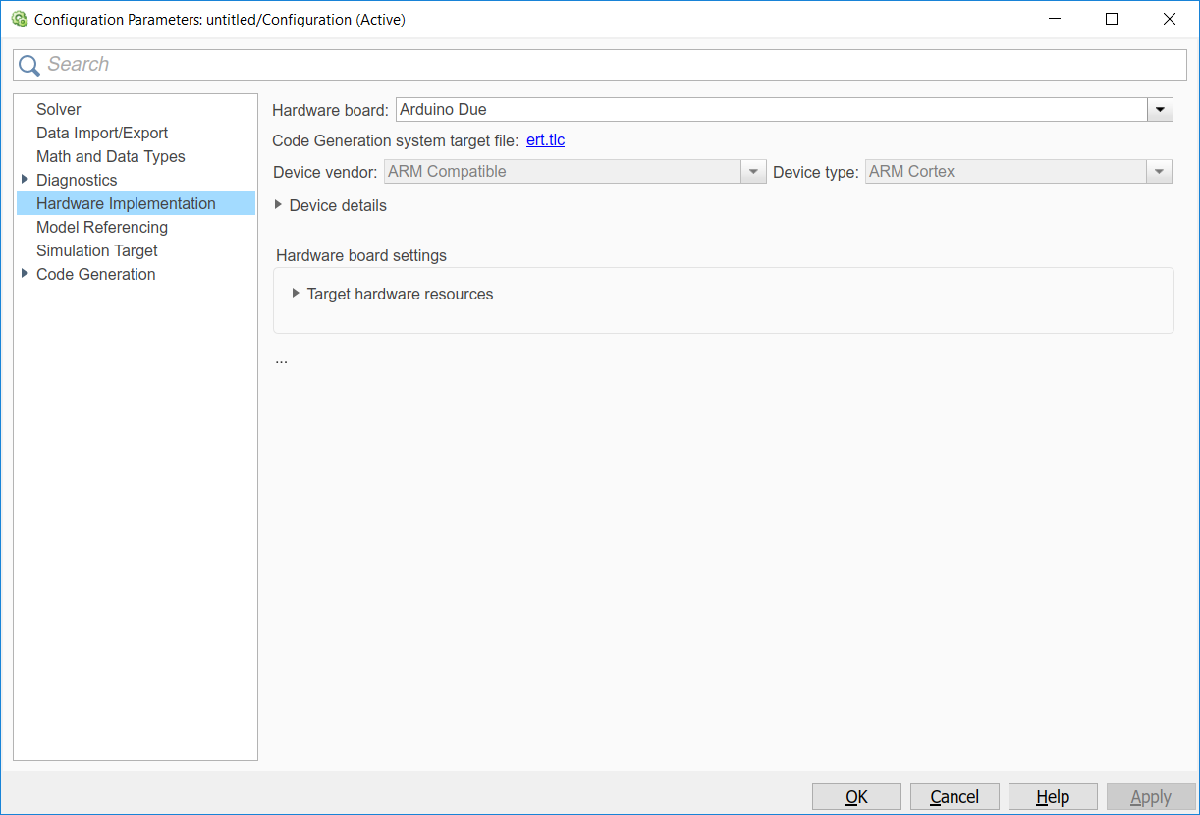

***Modo de simulación***

Como el hardware a usar es un hardware externo, el modo en el que se ejecuta el modelo de Simulink tiene que ser “***external***”. Gracias a este modo, conectamos el diagrama de bloques creado en Simulink con nuestra aplicación, el cual ejecuta el modelo en el hardware de destino.

Además de esto, también nos aporta la opción de compilar el código y transferirlo a nuestro microcontrolador, así, el modelo no tendrá que estar conectado a Simulink. Para ello se usa el botón "***Deploy to Hardware***".

***Tiempo de ejecución***

El tercer concepto a tener en cuenta es el tiempo de ejecución, gracias a esta opción, podemos elegir el tiempo que se desea que el modelo este en ejecución. Si se desea ejecutarlo hasta una cierta interrupción, se delimitará escribiendo “***Inf***”.

Teniendo en cuenta estos tres pasos, podemos ahora interactuar con el Arduino mediante Simulink. Es por eso que en la siguiente sección se realizaran varios ejercicios con los cuales aprenderemos lo básico para poder manejarnos con ello.

# Ejercicios

En esta sección se realizan varios ejercicios con los cuales se interiorizarán más fácilmente los conceptos de entradas y salidas digitales y analógicos de Arduino usando para ello la hoja de Simulink.

***Ejercicio 1******: Salida digital***

Este primer ejercicio trata de encender el led integrado del microcontrolador. Este led está incorporado en casi todas las placas de Arduino y su enumeración varia respecto al modelo en uso. En el caso del Arduino Due, este led está conectado al pin 13, es por eso que se ha realizado el siguiente diagrama de bloques.

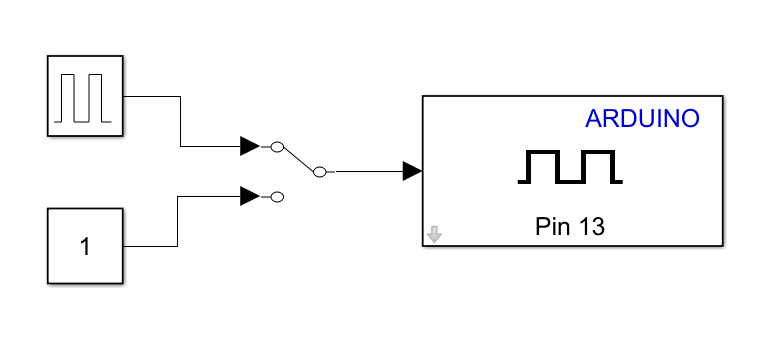

Gracias a este diagrama de bloques podremos analizar como encender un led mediante 0 y 1 o mediante una señal de pulsos accionando para ello el interruptor manual.

Para saber a qué pin está conectado el led integrado de tu placa  Arduino: [https://www.arduino.cc/en/Tutorial/Blink](https://www.arduino.cc/en/Tutorial/Blink) 

if OpenModel
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open DigitalOut.slx
end

***Ejercicio 2:****** Entrada digital***

Este segundo ejercicio consiste en obtener una señal digital mediante un botón. Cuando el botón este pulsado, hay que obtener un 1 booleano en el scope de Simulink. Por consiguiente, cuando no se acciona el botón, lo que obtendremos será un 0. Para ello, se ha creado el siguiente diagrama de bloques.

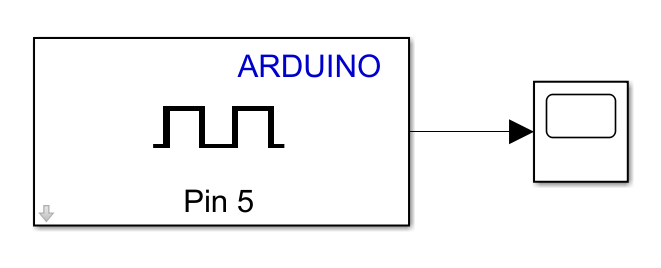

Junto con el siguiente circuito:

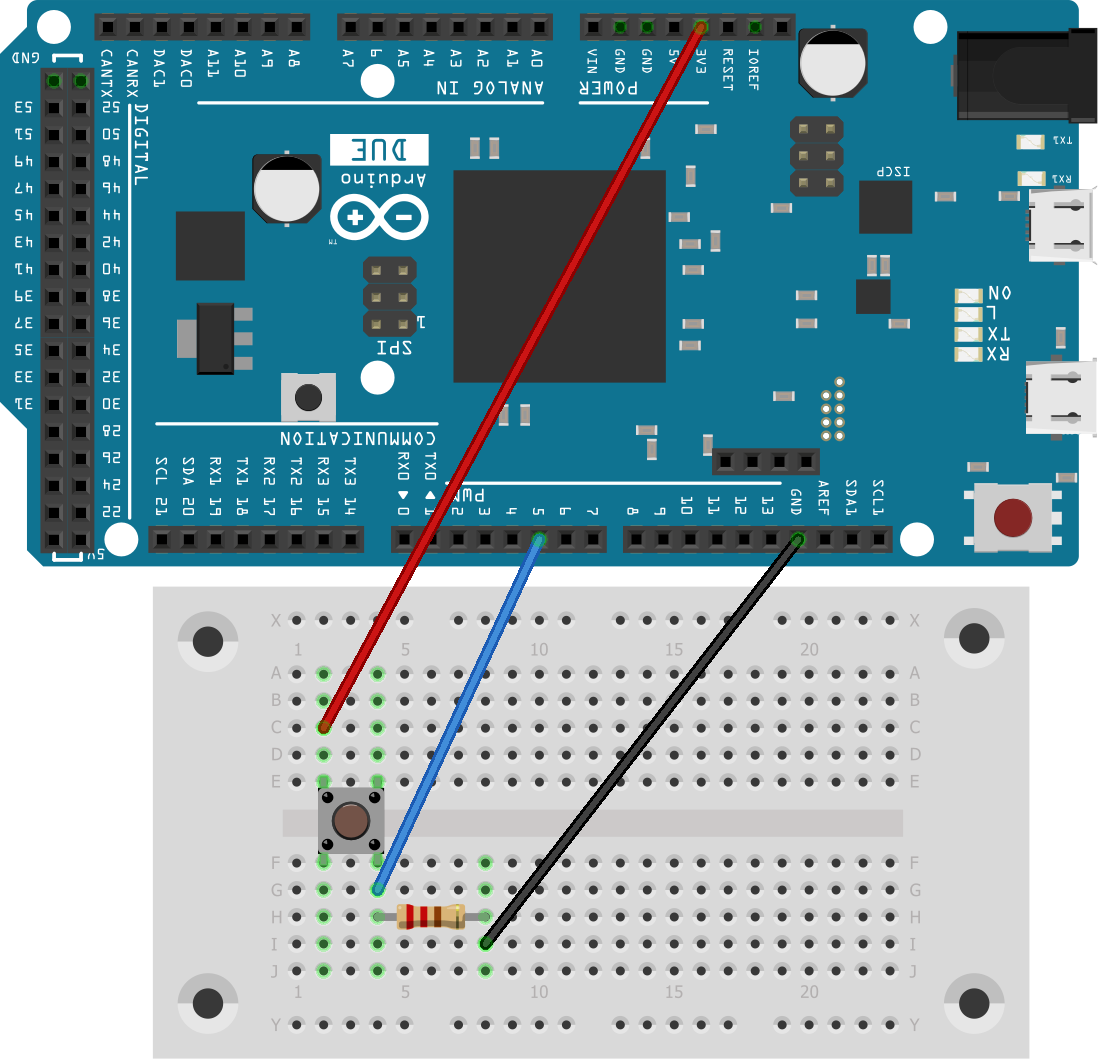

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open DigitalIn.slx
end

***Ejercicio 3:****** Salida analógica***

Se desea encender un led mediante señal analógica. Para ello, usaremos los pines llamados DAC del Arduino Due. Estos pines son los encargados de convertir una señal digital en analógica. Se desea encender y apagar un led progresivamente y a distintas frecuencias, es por eso que se ha diseñado el siguiente diagrama de bloques.

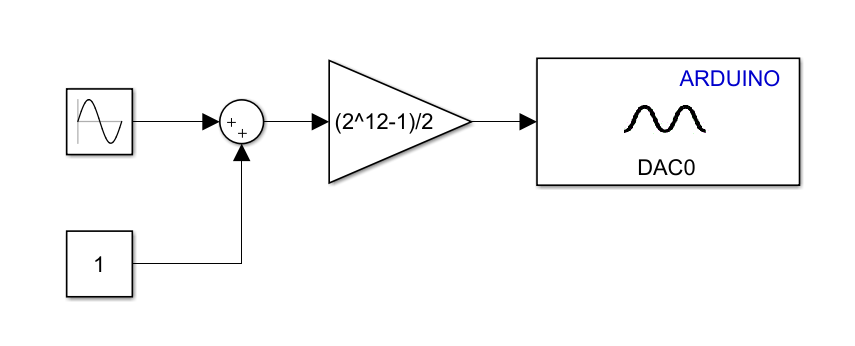 

Se le aplica una señal senoidal centrada en 0.5 y de amplitud de 0.5. Con lo cual el led parpadeara a la frecuencia de la señal senoida. Para ello, se ha creado el siguiente circuito:

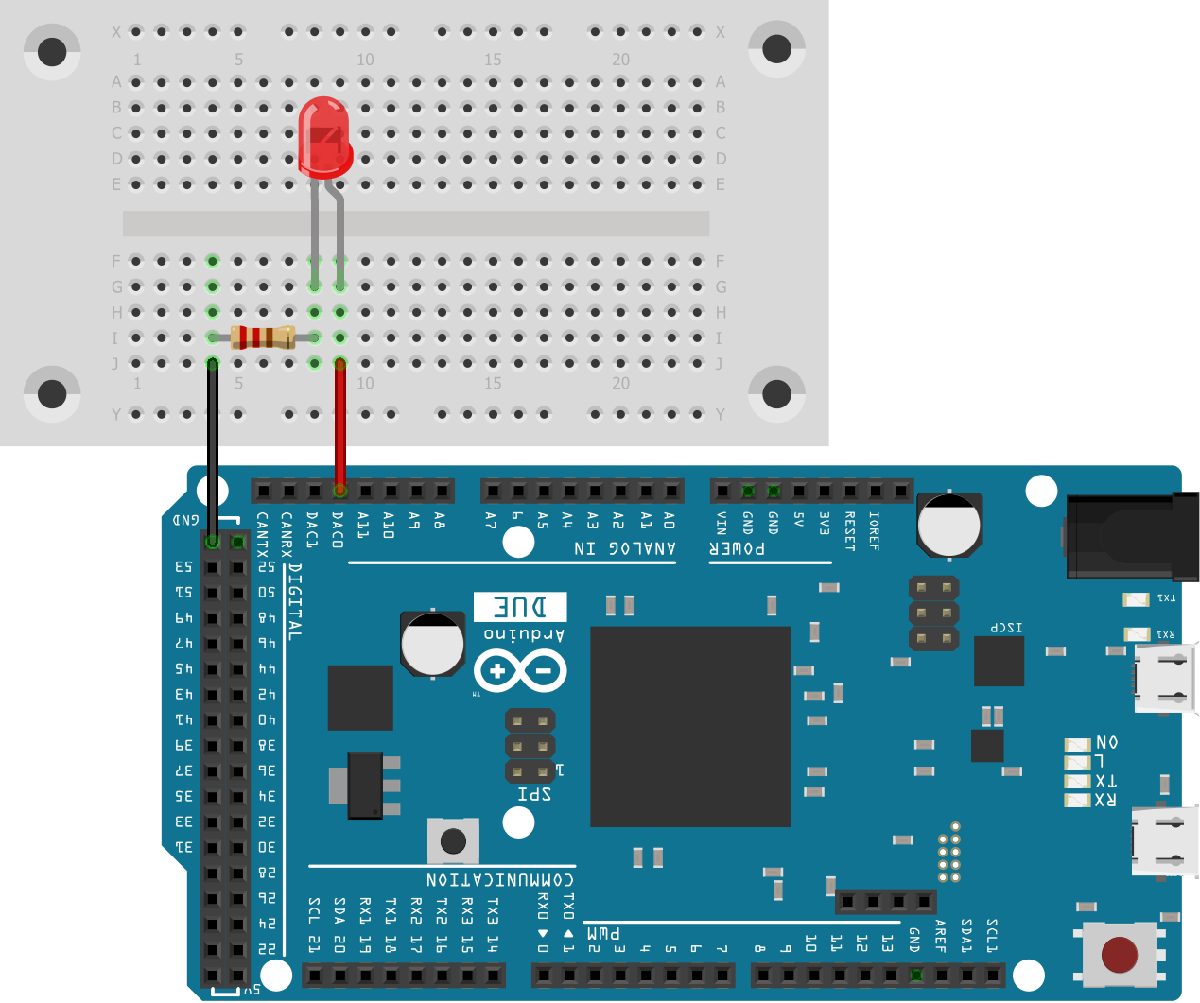

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open AnalogOut.slx
end

***Ejercicio 4:****** Entrada analógica***

Por último, se desea obtener una señal analógica. Para ello se ha utilizado un potenciómetro y se ha diseñado el siguiente diagrama de bloques.

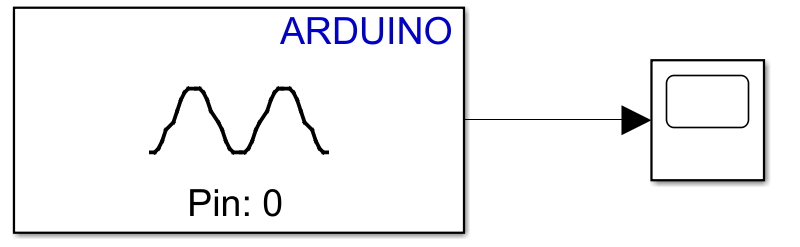

En este caso, el circuito creado es el siguiente:

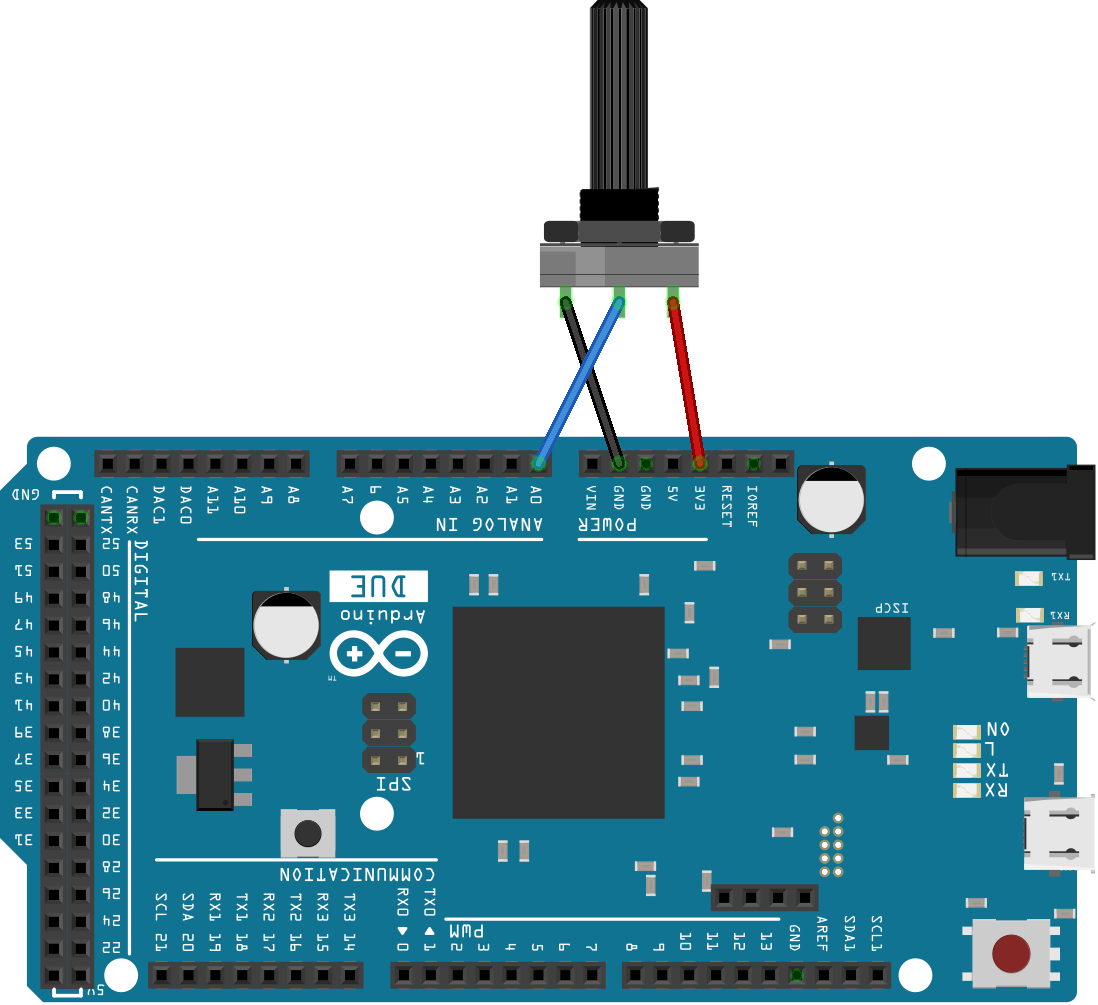

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open AnalogIn.slx
end

***Conclusión:***

Una vez entendiendo estos cuatro conceptos se pueden crear diagramas de bloques donde se mezclen todos estos conceptos mencionados anteriormente y poder así crear un sistema de control. Para más ejemplos de Arduino en MATLAB o Simulink:

Ejemplos MATLAB & Arduino: [https://es.mathworks.com/help/supportpkg/arduinoio/examples.html](https://es.mathworks.com/help/supportpkg/arduinoio/examples.html) 

Ejemplos Simulink & Arduino: [https://es.mathworks.com/help/supportpkg/arduino/examples.html](https://es.mathworks.com/help/supportpkg/arduino/examples.html) 